% %doc imfilter;

% A = imread('cameraman.tif');

% %h = [0,8,0;9,0,9;0,7,0];

% %g = [0 1 0;1 -4 1;0 1 0];

% h = [-1 -1 -1; -1 8 -1; -1 -1 -1];

% h1 = [0,0,0;1,8,1;-1,-1,-1]

% A_enhance = imfilter(A,h,'conv');

% 

% figure,

% subplot(1,2,1);

% imshow(A);title('origin image');

% subplot(1,2,2);

% imshow(A_enhance);title('filtered image');

% [A,map] = imread('cameraman.tif');

% %ran_ = uint8(randn(256,256));

% %doc randn

% %A_new = A + ran_;

%   

% A_new = imnoise(A,'gaussian',10/256);

% figure,

% subplot(1,2,1);

% imshow(A);title('original image')

% subplot(1,2,2);

% imshow(A_new); title('Added white noise image')

% 

% figure,

% imshow(imfilter(A_new,fspecial('motion',3,45)));

# Exercise 5 

## 1. Laplacian filter with high-boost filtering

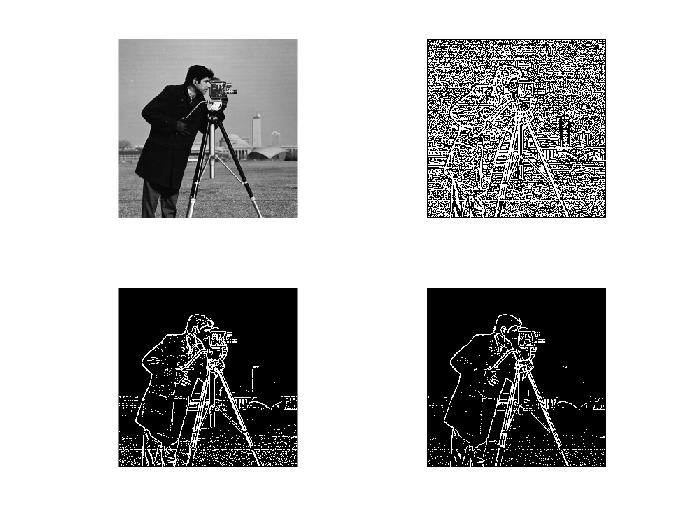

% filter_size = 3
%  filters = zeros(filter_size, filter_size, 4)
%  filters((filter_size + 1)/2, :, 1) = ones(1, filter_size)
%  filters(:, :, 3) = filters(:, :, 1)
%  filters(:,:,4) = eye(filter_size)
%  filters(:, :, 2) = fliplr(filters(:, :, 4));
%  filters = filters ./ sum(filters, [1, 2]);
    
 im = imread('cameraman.tif');
centers = -[8 9 9.7];
filters = ones(3, 3, 3);
% size(im)
% length(centers)
im_filtered = zeros([size(im) length(centers)]);

% create a kernel
for i = 1:length(centers)
    filters(2, 2, i) = centers(i);
end

for i = 1:length(centers)
    im_filtered(:, :, i) = imfilter(im, filters(:, :, i));
end

figure;
subplot(2, 2, 1);
imshow(im);
for i = 1:length(centers)
    subplot(2, 2, i + 1);
    imshow(im_filtered(:, :, i));
end

## 2. Directional filtering

## Generate noise

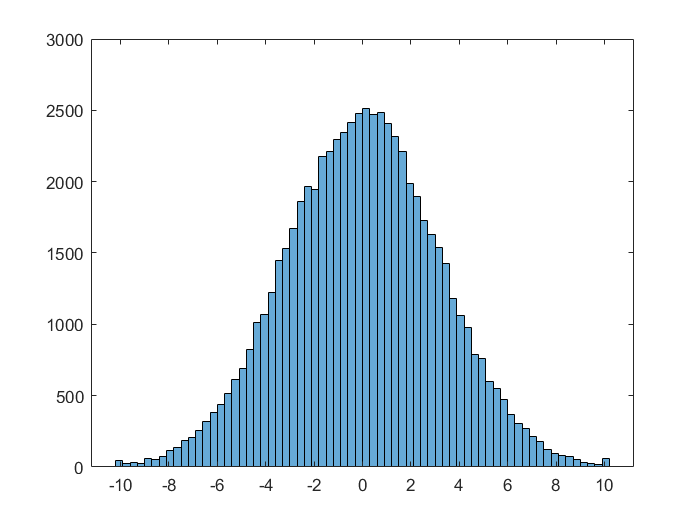

noise = wgn(size(im, 1), size(im, 2), 10);
noise = min(noise, 10);
noise = max(-10, noise);

figure;
histogram(noise(:))

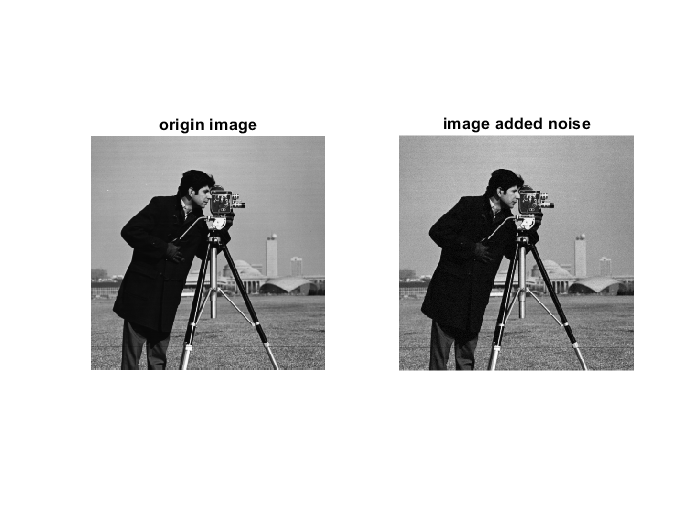


% Add noise to image
im_wgn = uint8(double(im) + noise);

figure;
subplot(1, 2, 1);
imshow(im);title('origin image')
subplot(1, 2, 2);
imshow(im_wgn);title('image added noise')


%% Use directional_filtering function
%% Kernel size 3x3
[im_0deg_3, im_45deg_3, im_90deg_3, im_135deg_3] = directional_filtering(double(im_wgn), 3);
'directional filter with filter size = 3'

ans = 'directional filter with filter size = 3'

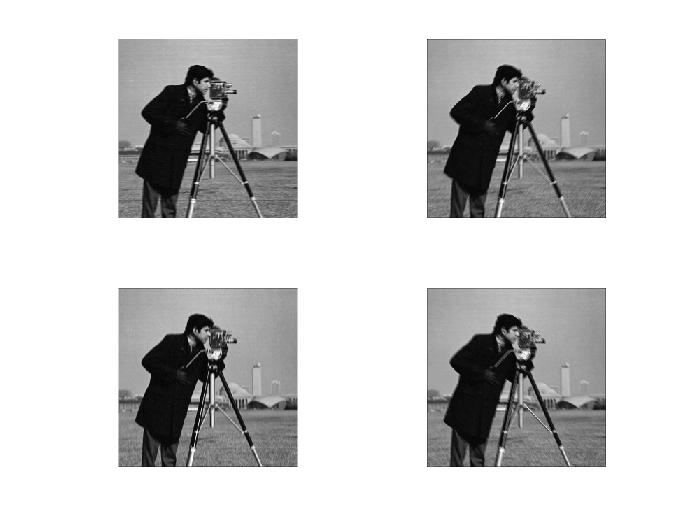

figure;
subplot(2, 2, 1);
imshow(im_0deg_3);
subplot(2, 2, 2);
imshow(im_45deg_3);
subplot(2, 2, 3);
imshow(im_90deg_3);
subplot(2, 2, 4);
imshow(im_135deg_3);

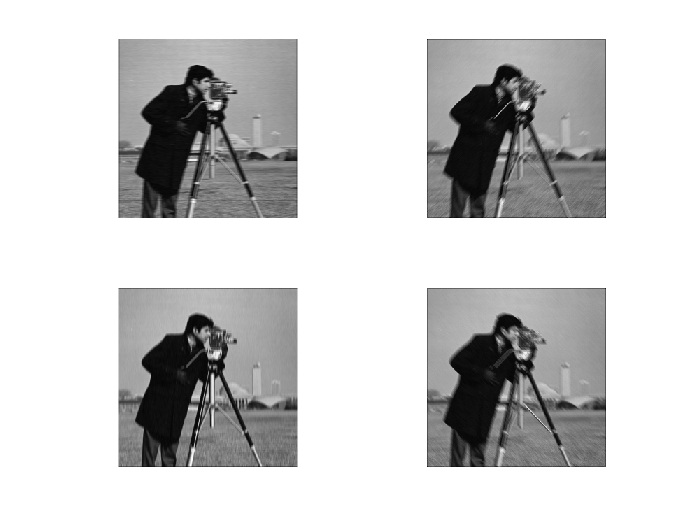

%% Kernel size 5x5
[im_0deg_5, im_45deg_5, im_90deg_5, im_135deg_5] = directional_filtering(double(im_wgn), 5);

figure;
subplot(2, 2, 1);
imshow(im_0deg_5);
subplot(2, 2, 2);
imshow(im_45deg_5);
subplot(2, 2, 3);
imshow(im_90deg_5);
subplot(2, 2, 4);
imshow(im_135deg_5);

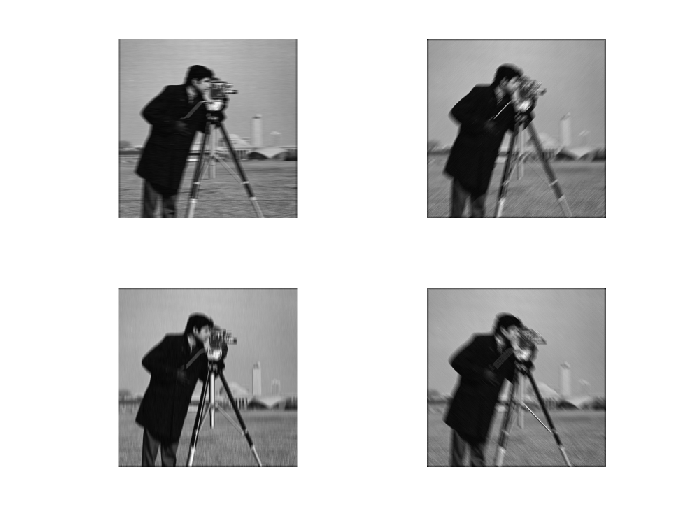

%% Kernel size 7x7
[im_0deg_7, im_45deg_7, im_90deg_7, im_135deg_7] = directional_filtering(double(im_wgn), 7);

figure;
subplot(2, 2, 1);
imshow(im_0deg_7);
subplot(2, 2, 2);
imshow(im_45deg_7);
subplot(2, 2, 3);
imshow(im_90deg_7);
subplot(2, 2, 4);
imshow(im_135deg_7);

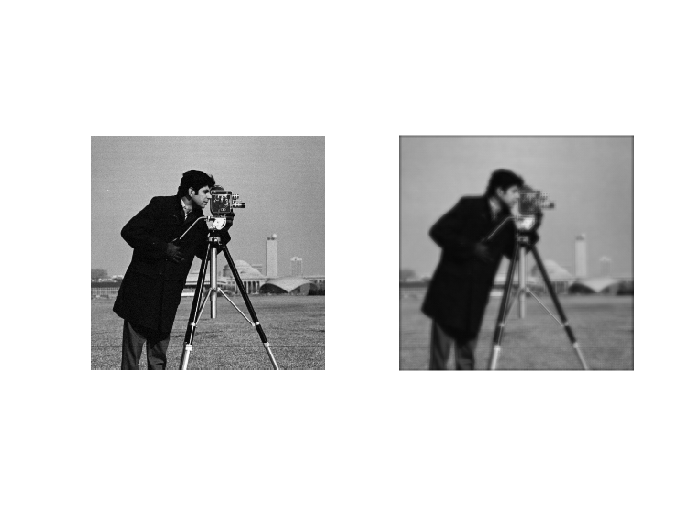

% Combine the result from 4 filtered image
% Sum the image. Make the image blur
im_sum = (double(im_0deg_7) + double(im_45deg_7) + double(im_90deg_7) + double(im_135deg_7))/4;
figure;
subplot(1, 2, 1);
imshow(im_wgn);
subplot(1, 2, 2);
imshow(uint8(im_sum));

## 3. Threshold Median Filtering

im = imread('miranda1.tif');
noise = zeros(size(im));
noise(151:250, 151:250) = wgn(100, 100, 30);
im_noise = uint8(double(im) + noise);

## Filter size of 3x3

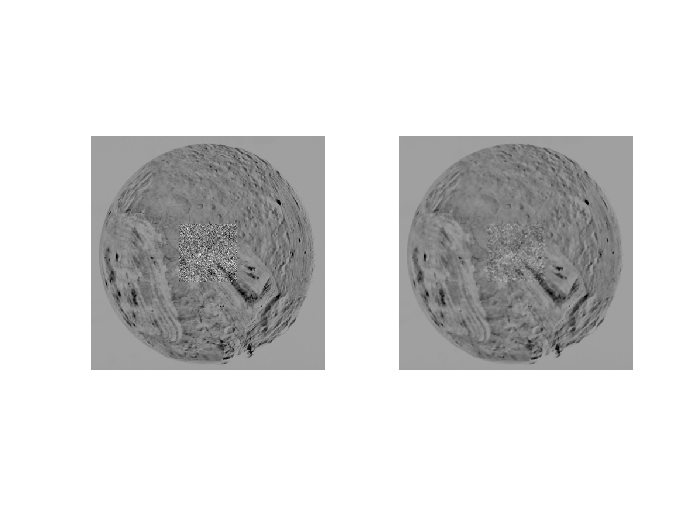

im_med_filter_3 = med_filter(im_noise, 3);

figure;
subplot(1, 2, 1);
imshow(im_noise);
subplot(1, 2, 2);
imshow(im_med_filter_3);

## Filter size of 5x5

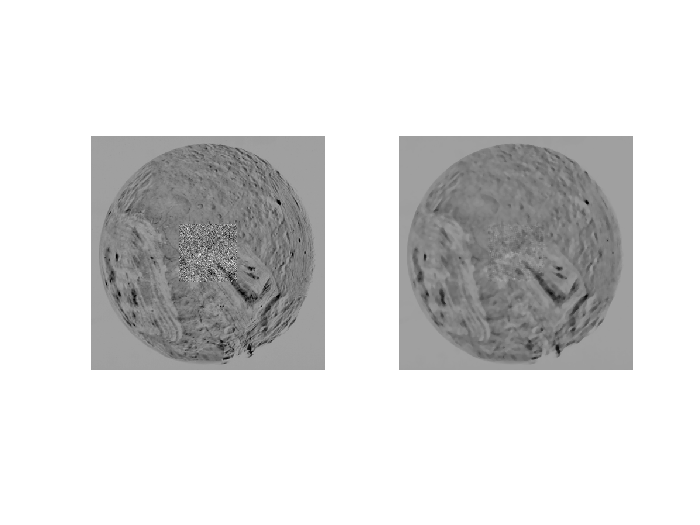

im_med_filter_5 = med_filter(im_noise, 5);

figure;
subplot(1, 2, 1);
imshow(im_noise);
subplot(1, 2, 2);
imshow(im_med_filter_5);

## Filter size of 7x7

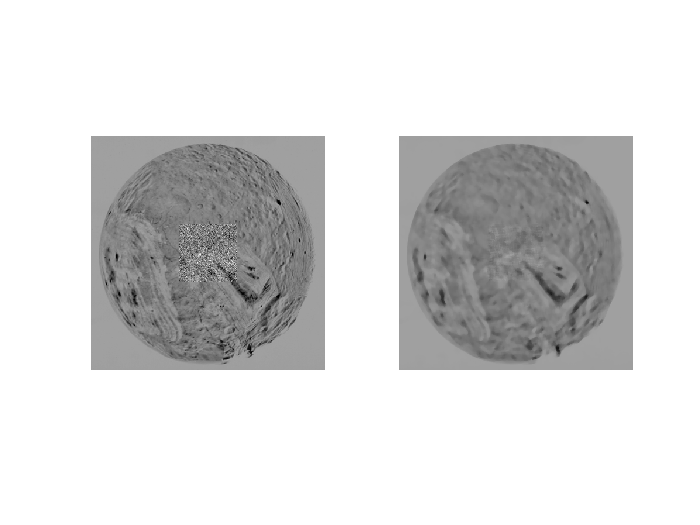

im_med_filter_7 = med_filter(im_noise, 7);

figure;
subplot(1, 2, 1);
imshow(im_noise);
subplot(1, 2, 2);
imshow(im_med_filter_7);

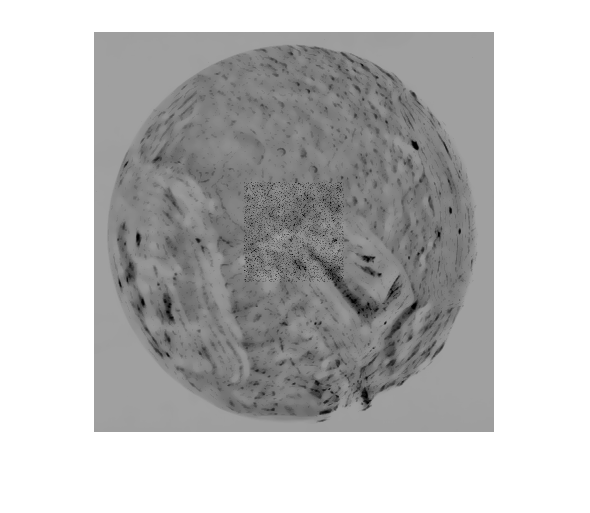


figure,
im_med_filter_7_thres = med_filter_threshold(im_noise,7,6);
imshow(im_med_filter_7_thres)

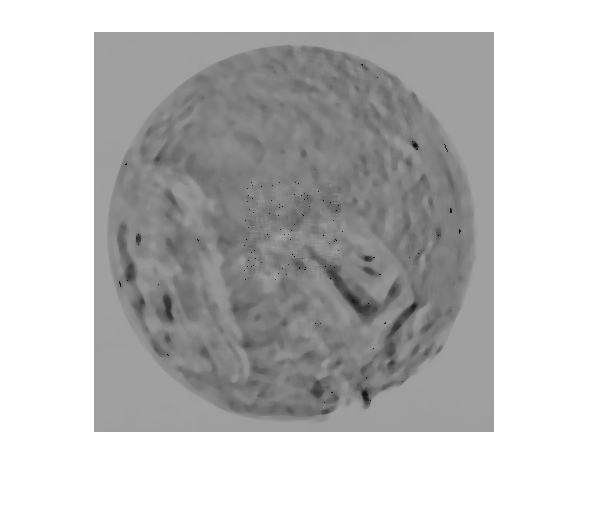


im_med_filter_7_thres_100 = med_filter_threshold(im_noise,7,80);
imshow(im_med_filter_7_thres_100)

## Median filter with threshold

threshold = [5 10 20 40 80 100 150 200];

for t = 1:length(threshold)

    im_med_filter = med_filter_threshold(im_noise, 5, threshold(t));

    figure;

    subplot(1, 2, 1);

    imshow(im_noise);

    subplot(1, 2, 2);

    imshow(im_med_filter);

end

im = imread('cameraman.tif');

noise = zeros(size(im));

noise(79:178, 79:178) = wgn(100, 100, 30);

im_noise = uint8(double(im) + noise);

for t = 1:length(threshold)

    im_med_filter = med_filter_threshold(im_noise, 5, threshold(t));

    figure;

    subplot(1, 2, 1);

    imshow(im_noise);

    subplot(1, 2, 2);

    imshow(im_med_filter);

end